K=95;
jump(25000,800,K)

ans = 11.0183

jump(100000,1600,K)

ans = 10.8380

jump(400000,3200,K)

ans = 10.8351

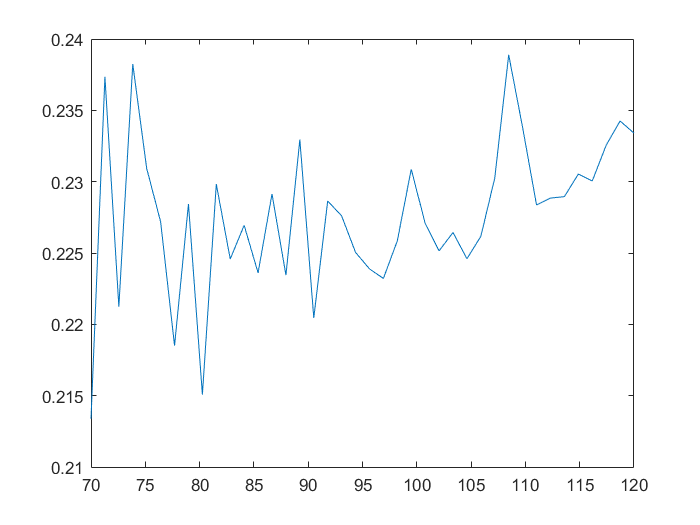

val = zeros(40,1);
implied = zeros(40,1);
k_to_try = transpose(linspace(70,120,40));
for i = 1:40
    val(i) = jump(25000,800,k_to_try(i));
    implied(i) = blsimpv(95,k_to_try(i),0.05,1, val(i));    
end

plot(k_to_try, implied)

we observed a voliativity smile, when K is low, implied voliativity is very high, Then for a short intervel implied voliativity decrease quickly. after some value of K below S0,  implied voliativity seems to increase slowly.

however, the curves are not smooth. And implied voliativity is always above our true voliativity, which makes sense as blsimpv doesn't consider jump behavior, which should increase voliativity.

function [val] = jump(M,N,K)
    sigma=0.2;
    r=0.05;
    muu=0.32 ;
    mud= 0.3;
    pup = 0.4;
    lambda = 0.1;
    T=1;
    dt=T/N ;
    kappa = 0.049;     
    
    % we update S and J at each timestep.
    S =ones(M,1).*95;
    J = zeros(M,1);    
    for timestep = 1:N
        jumpmask = rand(M,1)<(lambda*dt);
        [i,~,~] = find(jumpmask);
        nonzerolength = length(i);
        % normally, i would be length 0, and we skip these steps in if
        % statement
        if nonzerolength ~= 0
            upmask = rand(nonzerolength,1)<pup;
            % -log(J)~exp(mu), then we generate -log(J)=x and J=e^(-x)
            Jump = upmask.*exp(exprnd(muu,nonzerolength,1)) + ...
                (1-upmask).* exp(- exprnd(mud, nonzerolength,1));
            J(i,1) = Jump;
        end
        
        S=S+S.*(r-lambda*kappa)*dt+S.*sigma...
            .*sqrt(dt).*normrnd(0,1,M,1)+S.*(J-1).*jumpmask;
    end
    
    val = mean(exp(-r*T).*max(0,S-K));

end